% Load model
modelObj = sbmlimport('repressilator_sbml.xml');

% Define simulation settings
cs = getconfigset(modelObj);
cs.StopTime = 200; % to simulate 200 time units
set(cs.SolverOptions, 'OutputTimes', [1:0.001:200])
% Simulate
tic
[t, x, names] = sbiosimulate(modelObj);
toc

Elapsed time is 4.435527 seconds.


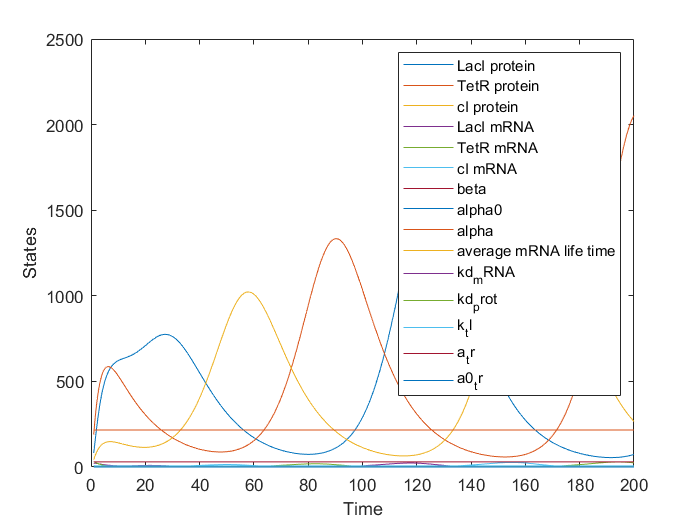

plot(t, x)
xlabel('Time')
ylabel('States')
legend(names)